View parameters, plot waveform, compute and display spectrum. Verify that the frequency of the sinusoid (as measured using the FFT) is the expected frequency. 

clear

## Load .wav file

[x, Fs] = audioread('author_f.wav');
[nbits, opts] = audioread('author_f.wav');

whos

  Name           Size             Bytes  Class     Attributes

  Fs             1x1                  8  double              
  nbits      25500x1             204000  double              
  opts           1x1                  8  double              
  x          25500x1             204000  double              



Fs

Fs =        16000


nbits

nbits =    0.915527343750000
   0.305175781250000
                   0
                   0
                   0
                   0
                   0
  -0.305175781250000
                   0
                   0


opts

opts =        16000


soundsc(x, Fs)

## Plot waveform

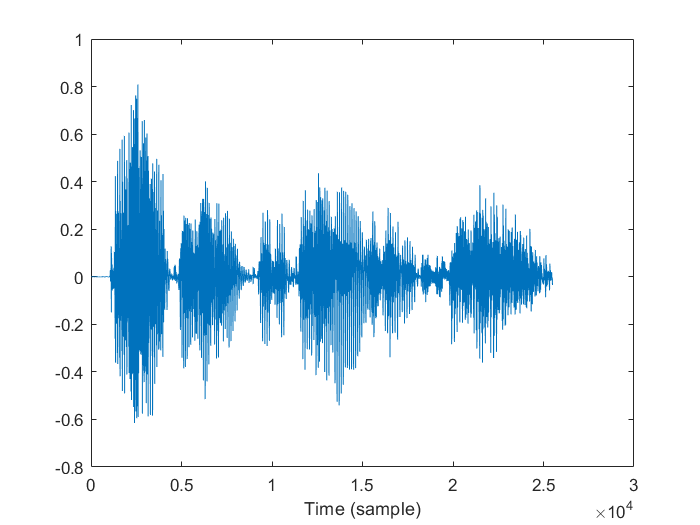

figure(1)
clf
plot(x)
xlabel('Time (sample)')

## Time axis in seconds

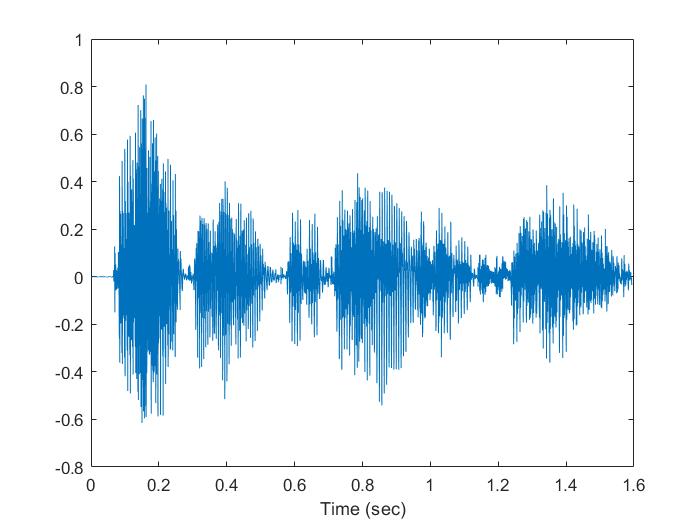

N = length(x);
t = (1:N)/Fs;

figure(1)
clf
plot(t, x)
xlabel('Time (sec)')

## Zoom in to 50 msec

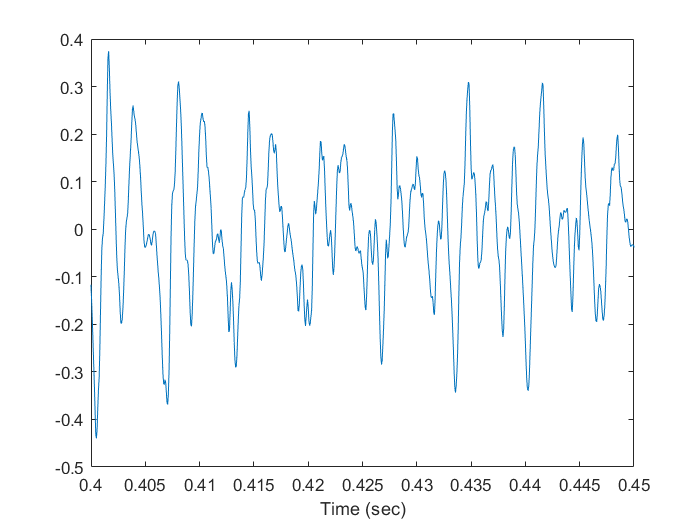

xlim(0.4 + [0 0.050])

%imp = [1  zero(1,N)];
%h = filter (x, imp)

%figure(1)
%clf
%stem(0:N,h)
%xlabel('Discrete time(n)')
%title('impulse response')




## Frequency spectrum

Use Fast Fourier Transform (FFT)

% Use power of 2 for FFT efficiency
N = length(x)

N =        25500


Nfft = 2^ceil(2+log2(N))        % Use FFT length longer than signal length

Nfft =       131072


## Compute Fourier transform

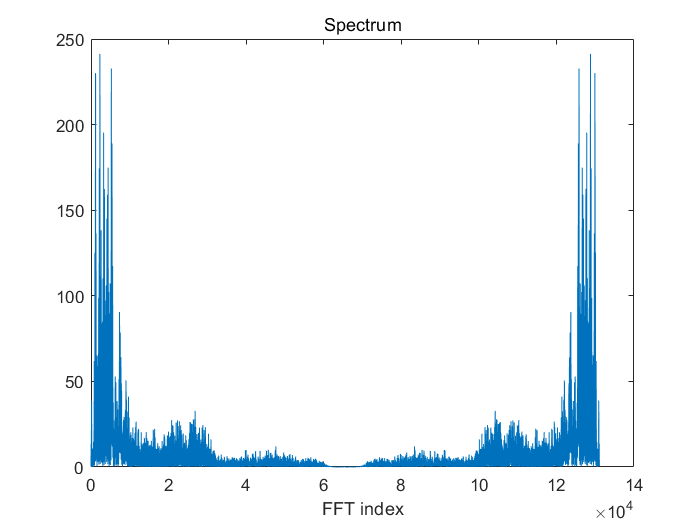

X = fft(x, Nfft);   
k = 0:Nfft-1;      % FFT index

figure(1)
clf
plot(k, abs(X))
xlabel('FFT index')
title('Spectrum')

## Center dc

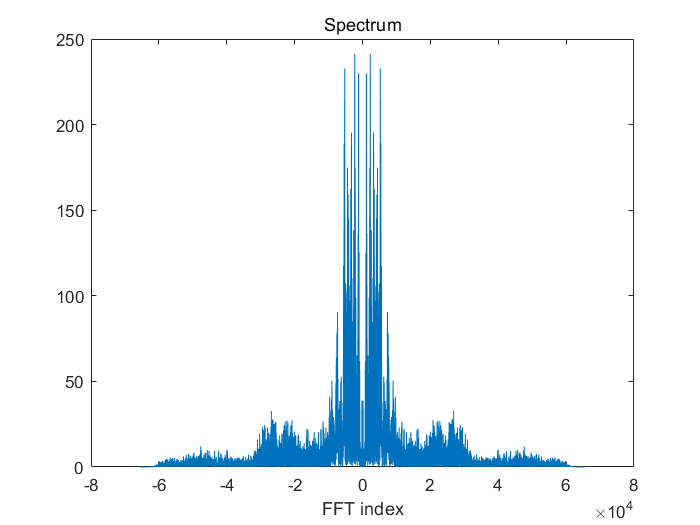

X2 = fftshift(X);
k2 = -Nfft/2 : Nfft/2-1;

figure(1)
clf
plot(k2, abs(X2))
xlabel('FFT index')
title('Spectrum')

## Normalized frequency

Normalized frequency is in units of [cycles per sample]

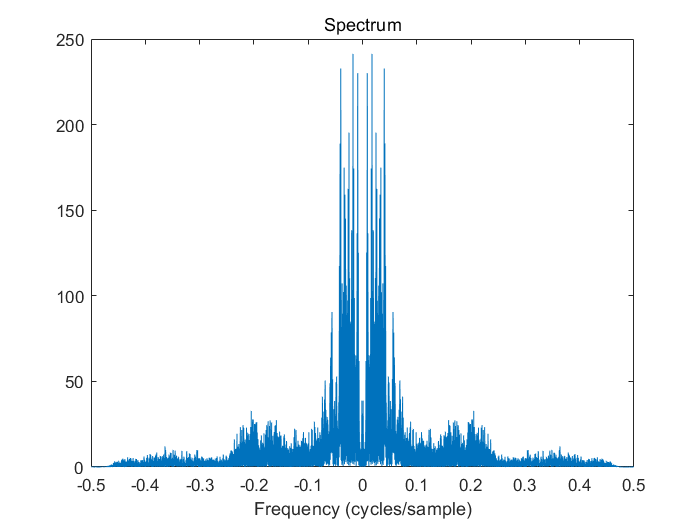

fn = ( -Nfft/2 : Nfft/2-1 ) / Nfft;

figure(1)
clf
plot(fn, abs(X2))
xlabel('Frequency (cycles/sample)')
title('Spectrum')

## Frequency in Hz

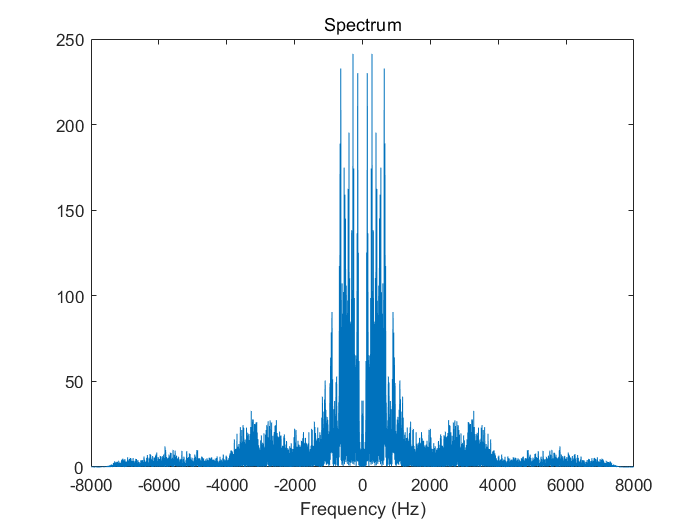

f = fn * Fs;

figure(1)
clf
plot(f, abs(X2))
xlabel('Frequency (Hz)')
title('Spectrum')

Zoom to frequency band [200 350] Hz. Notice the sidelobes

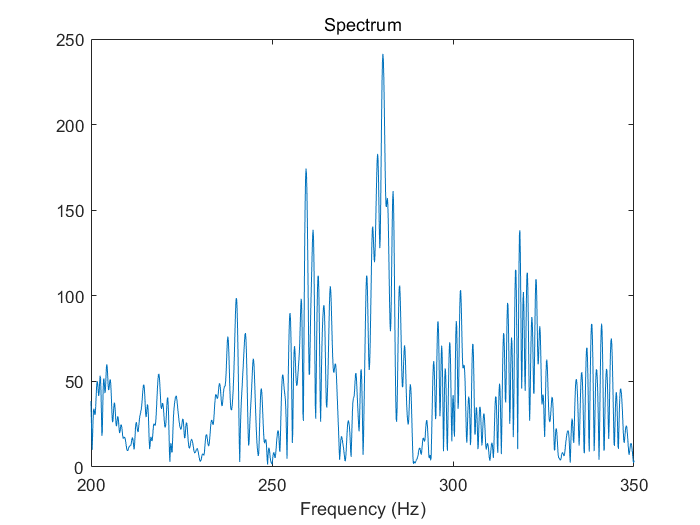

xlim([200 350])

## Fourier transform in dB

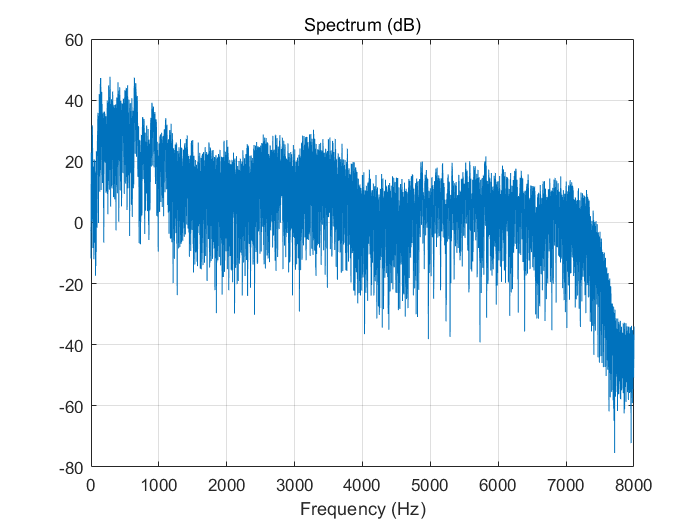

X_dB = 20*log10(abs(X2));

figure(1)
clf
plot(f, X_dB)
xlabel('Frequency (Hz)')
title('Spectrum (dB)')

xlim([0 Fs/2])
grid